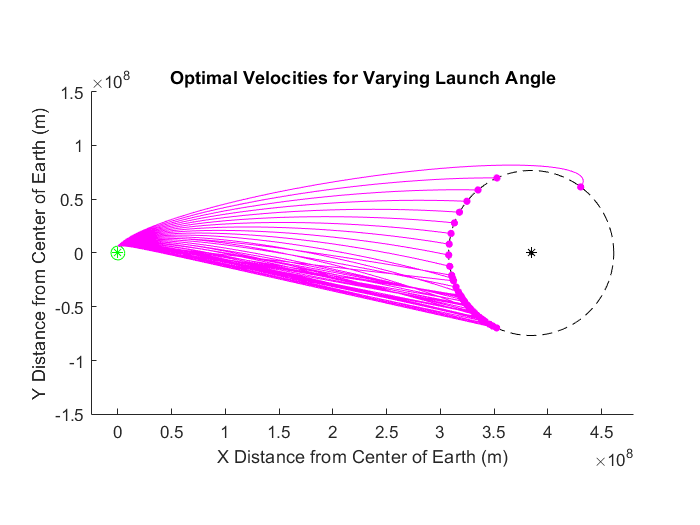

% Body trajectory examples

% Plot Earth, Moon, and satelite orbit
plot_earth_moon()

% Parameter sweep angle and velocity and only plot the most optimal
% velocity for each angle
optimizedVelocity = [];
for launchAngle = 0:1:80
    flag = 0;
    for launchVelocity = 10000:100:16000
        [T, M] = body_2D_ode45(launchAngle, launchVelocity);
        if T(end) ~= 60*60*24*7
            optimizedVelocity = [optimizedVelocity; launchAngle, launchVelocity];
            plot(M(:,1), M(:,2),'m');
            plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)
            flag = 1;
        end
            if flag == 1
                break;
            end
    end 
end
title('Optimal Velocities for Varying Launch Angle')

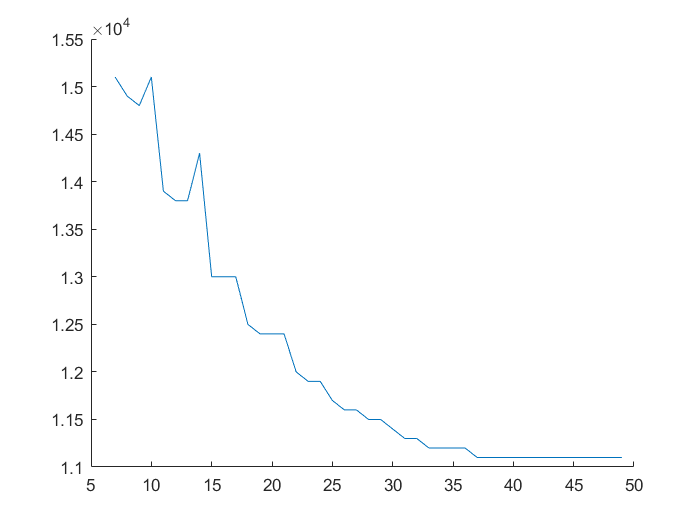

figure(2); clf; hold on;
plot(optimizedVelocity(:,1),optimizedVelocity(:,2))